# 4.1

*note : m and other variables are extracted from equation, in functions down this file*

m = 0;

breaking $0\le x\le 2$ to 200 parts and $0\le t\le 10$ to 201 parts:

x = linspace(0,2,200);
t = linspace(0,10,201);

solving equation:

- `sol` is 3-d array that is ($t_i \;,x_j \;,u_k$)

sol = pdepe(m,@heatEq,@heatInit,@heatBC,x,t);
u = sol(:,:,:);

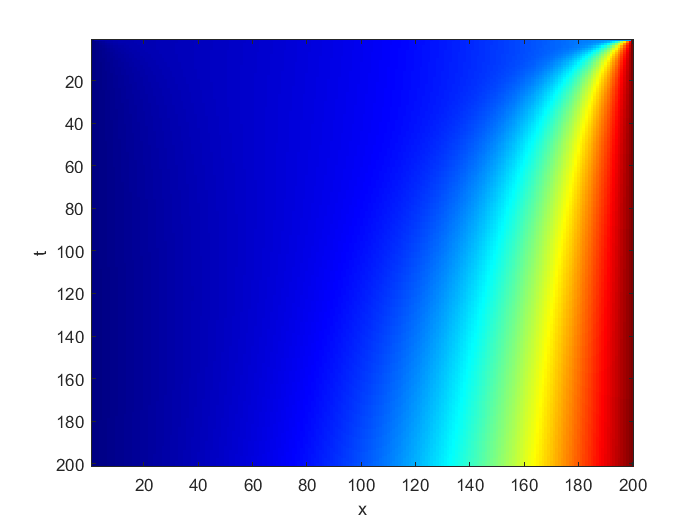

colormap("jet");
imagesc(sol)
xlabel('x')
ylabel('t')

when we are at t = 0:

- object's temperature mutate at x = 200

as time pass t$\to 200:$

- if we consider $i>j$ we have temperature of x at $t_i$ is higher than same point's temeperature at $t_j$.

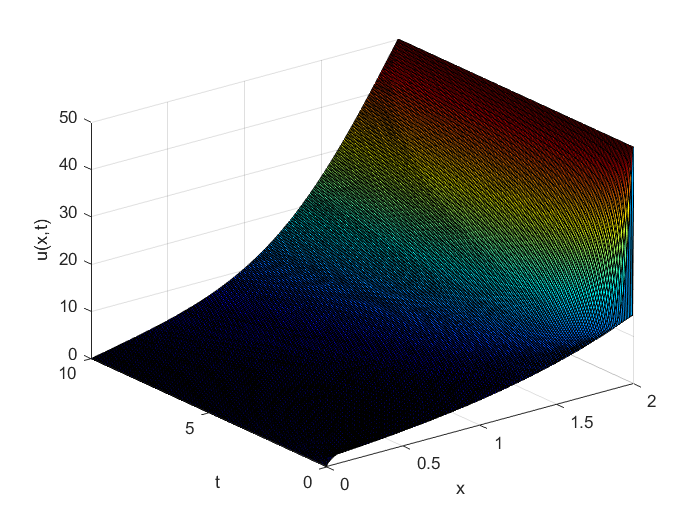

surf(x,t,u)
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

we can see:

- BC's temperature doesn't change by passing time and it is fixed for $x=0\Longrightarrow \textrm{temp}=0\;\textrm{and}\;x=2\Longrightarrow \textrm{temp}=50$

- in t = 0 x is it's init ${2e}^x$

- by passing time temperature of parts of disc which are near to right BC is increasing and getting close to 50, and small part of disc near left BC is loosing temperature and getting close to 0.

- at any time, as we increase x, temp will be increased too, it means du/dx is ascending.

we extract x temperature in t = 0 from `sol` 

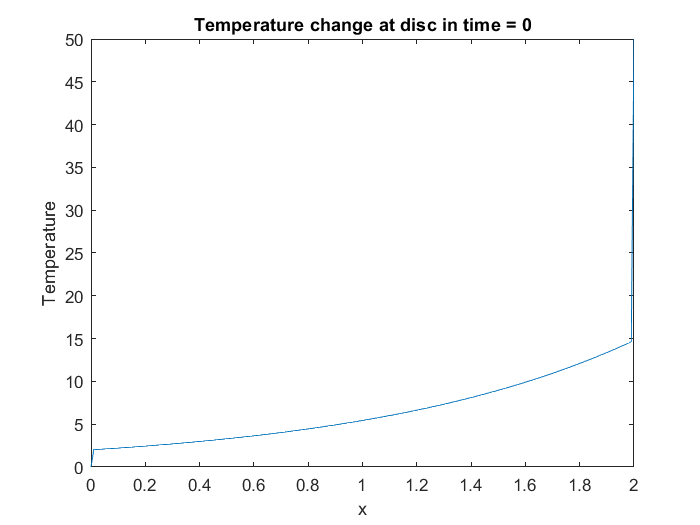

u_t0 = sol(1,:,:);
plot(x,u_t0)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 0')

as we see x=0 and x=2 are their init value from equation and other part of disc is set by ${2e}^x$

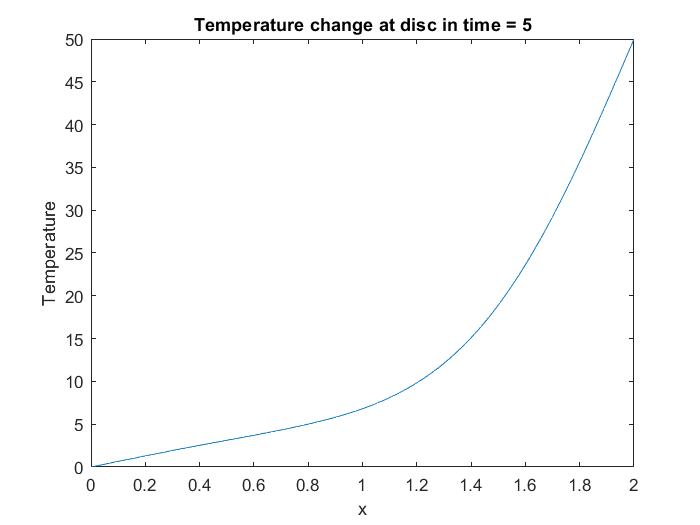

u_t5 = sol(100,:,:);
plot(x,u_t5)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 5')

as time pass, disc conducts heat and plot is loosing mutations and becomes more linear.

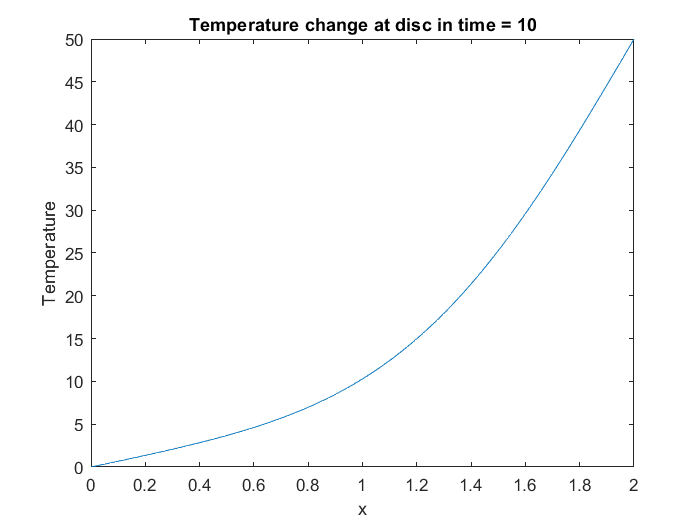

u_t10 = sol(201,:,:);
plot(x,u_t10)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 10')

repeating all proccess for new t and x partitioning:

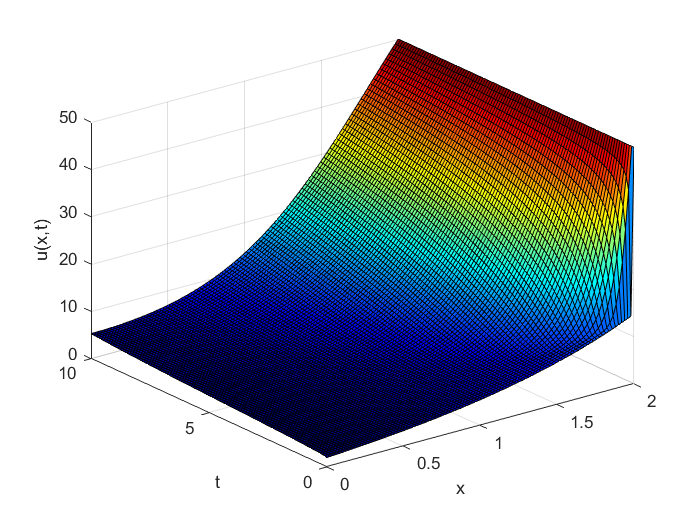

m = 0;
x = linspace(0,2,100);
t = linspace(0,10,101);
sol = pdepe(1,@heatEq,@heatInit,@heatBC,x,t);
u = sol(:,:,:);

surf(x,t,u)
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

colormap("jet")

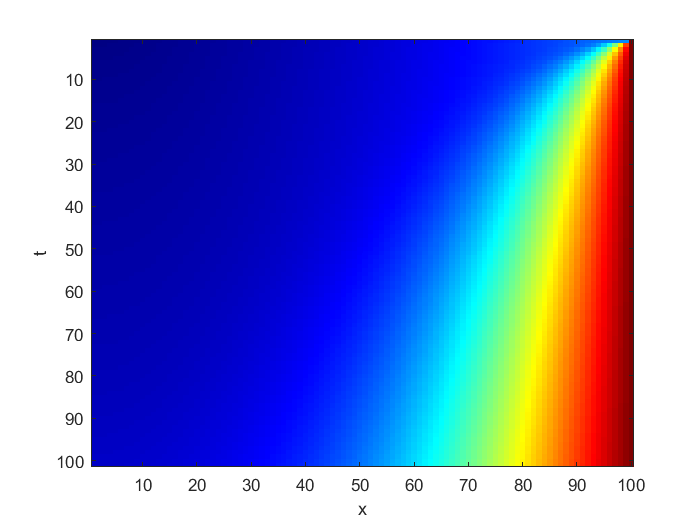

imagesc(sol)
xlabel('x')
ylabel('t')

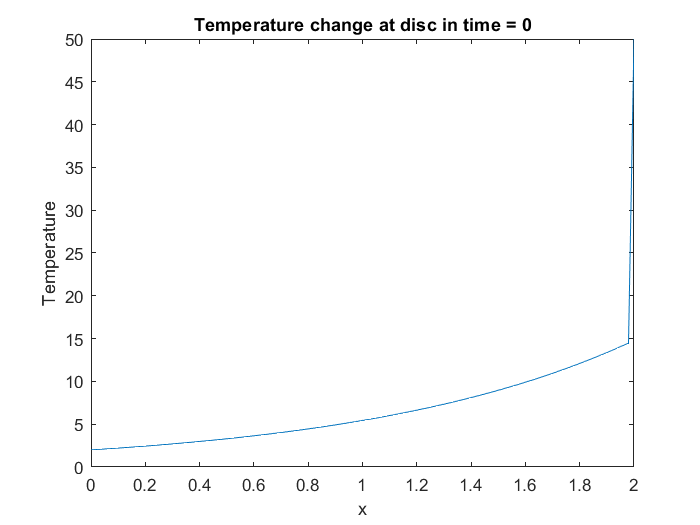


u_t0 = sol(1,:,:);
plot(x,u_t0)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 0')

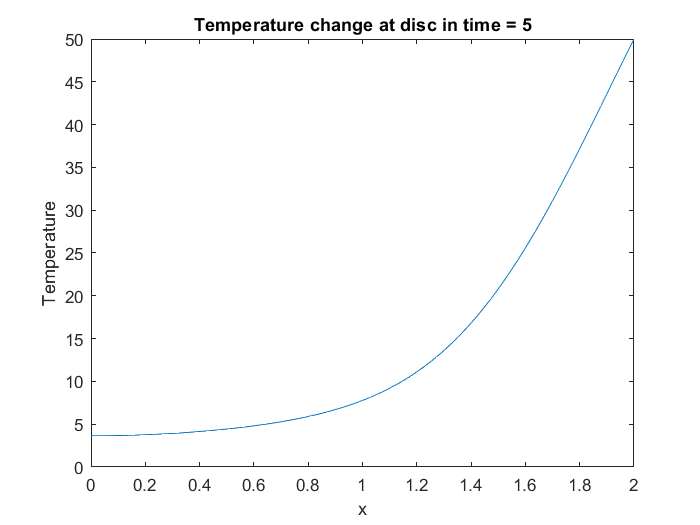


u_t5 = sol(50,:,:);
plot(x,u_t5)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 5')

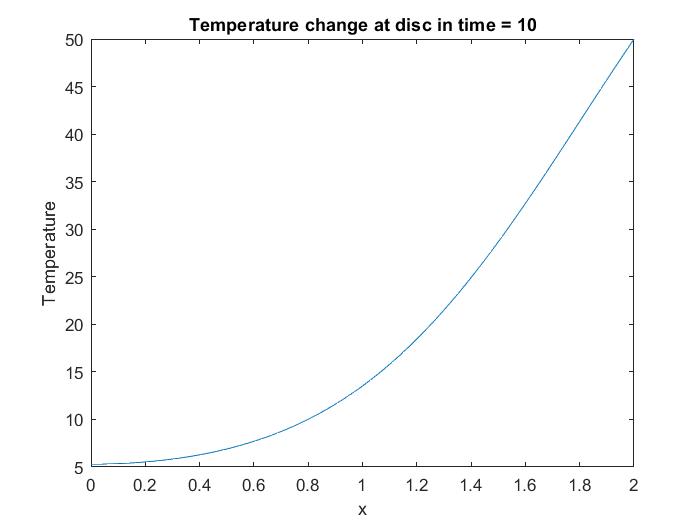


u_t10 = sol(101,:,:);
plot(x,u_t10)
xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 10')

only diffrent is plots is more round , because it is less accurate.

# 2

- time-indepent form of wave equation

- the real solotion for BC is zero.

- as we get away from bc and get close to center of disc, temeperature rises.

- the equation is symmetrical to x and y so temperature is similar in any specific radius.

we can write our equation like this :

$50\frac{\textrm{du}}{\textrm{dt}}=\frac{d}{\textrm{dx}}\left(\frac{\textrm{du}}{\textrm{dx}}\right)\to c=50,m=0,f=\frac{\textrm{du}}{\textrm{dx}},s=0$ :

function [c,f,s] = heatEq(x,t,u,dudx)
    c = 50;
    f = dudx;
    s = 0;
end


initial is $2e^x :$

function u0 = heatInit(x)
    u0 = 2*exp(x);
end

for BC we can do like this:

- left BC : $u_l -0=0\to p_l =u_l ,q_l =0\;$

- right BC : $u_r -50=0\to p_r =u_r -50\;,q_r =0\;$

function [pl,ql,pr,qr] = heatBC(xl,ul,xr,ur,t)
    pl = ul - 0; 
    ql = 0; 
    pr = ur - 50;
    qr = 0; 
end

